# The Basics

%Load the data.
load EMGdataWeek10.mat

%tells you which variables you have in your data
%who

%for data_ch1 and data_ch2, row = trail + column = time
num_trials = size(data_ch1,1);

%sampling interval
dt = times_ms(2) - times_ms(1);

# Trial 1 Data from both channels

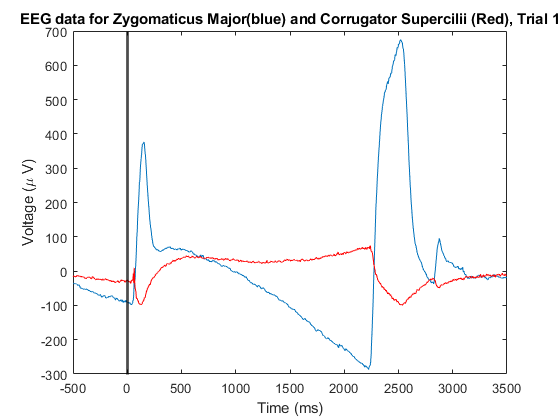

figure(1)
plot(times_ms, data_ch1(1,:)) %...data from zygomaticus major, trial 1
hold on
plot(times_ms,data_ch2(1,:), 'r') %... data from corrugator supercilii, trial 1
xlabel("Time (ms)")  %Label the x-axis as time.
ylabel("Voltage (\mu V)") %Label the y-axis as voltage.
title("EEG data for Zygomaticus Major(blue) and Corrugator Supercilii (Red), Trial 1")
xline(0, 'k', 'LineWidth', 2);
hold off %Release the current plot.

# EEG Data for ch1, All Trials

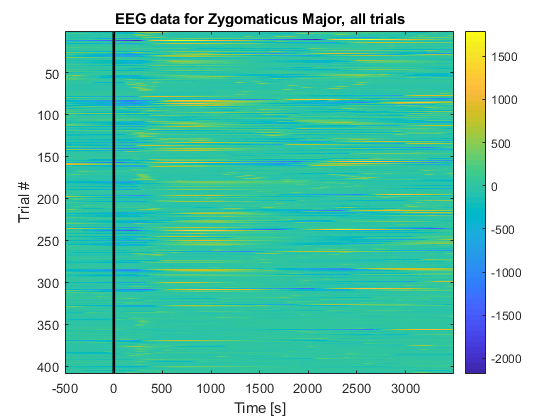

figure(2)
imagesc(times_ms,(1:num_trials),data_ch1); %Image the data from Zygomaticus Major.
colorbar;
xlabel('Time [s]') %Label the x-axis.
ylabel('Trial #') %Label the y-axis.
title("EEG data for Zygomaticus Major, all trials")
hold on %Indicate time of stimulus onset.
plot([0.25, 0.25], [0 1000], 'k', 'LineWidth', 2)
hold off

%warm colors = high voltages/ cool colors = lower voltages

# EEG Data for ch2, All Trials

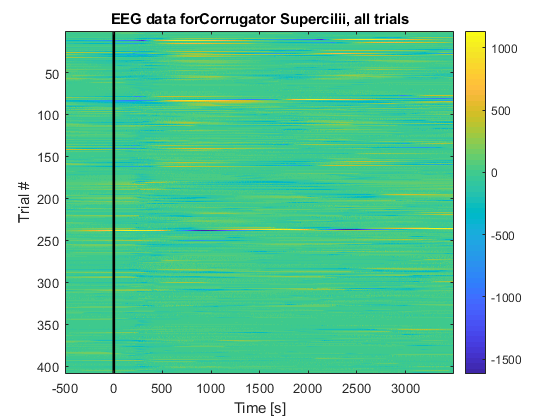

figure(3)
imagesc(times_ms,(1:num_trials),data_ch2); %Image the data from Corrugator Supercilii.
colorbar;
xlabel('Time [s]') %Label the x-axis.
ylabel('Trial #') %Label the y-axis.
title("EEG data forCorrugator Supercilii, all trials")
hold on %Indicate time of stimulus onset.
plot([0.25, 0.25], [0 1000], 'k', 'LineWidth', 2)
hold off

%warm colors = high voltages/ cool colors = lower voltages

# ERP (mean of all trials) of Ch1

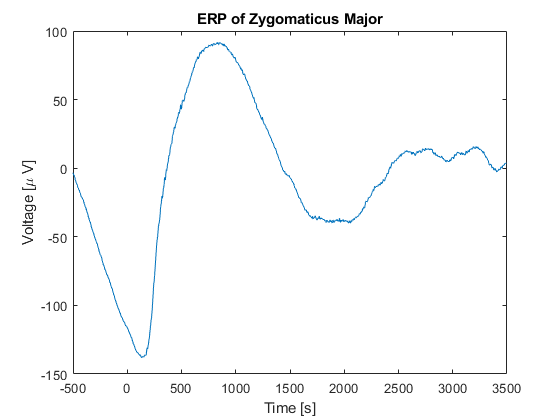

figure(4)
plot(times_ms, mean(data_ch1,1)) %Plot the ERP of Zygomaticus Major.
xlabel('Time [s]') %Label the x-axis as time,
ylabel('Voltage [\mu V]') %...and the y-axis as voltage,
title('ERP of Zygomaticus Major') %...and provide a useful title.

# ERP (mean of all trials) of Ch2

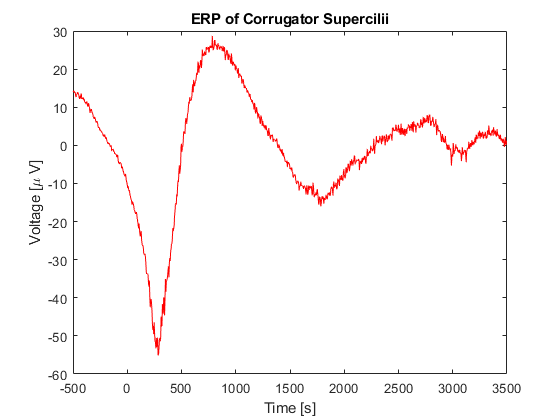

figure(5)
plot(times_ms, mean(data_ch2,1), 'r') %Plot the ERP of Corrugator Supercilii.
xlabel('Time [s]') %Label the x-axis as time,
ylabel('Voltage [\mu V]') %...and the y-axis as voltage,
title('ERP of Corrugator Supercilii') %...and provide a useful title.

# ERP of Ch1 for Smiling and Frowning

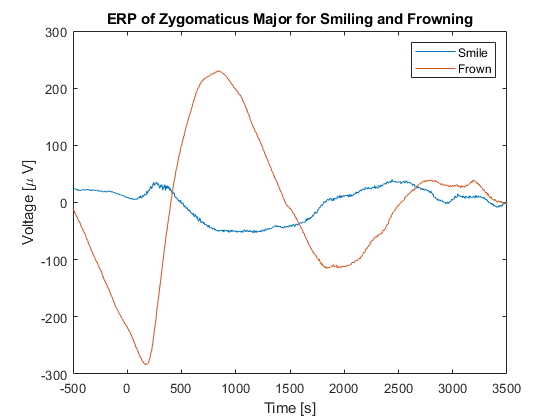

figure(6)
plot(times_ms, mean(data_ch1(labels == "S pressed",:)))
hold on
plot(times_ms, mean(data_ch1(labels == "F pressed",:)))
legend({"Smile", "Frown"})
xlabel('Time [s]') %Label the x-axis as time,
ylabel('Voltage [\mu V]') %...and the y-axis as voltage
title("ERP of Zygomaticus Major for Smiling and Frowning")
hold off

# EEG data for Ch1, all trials, smiling

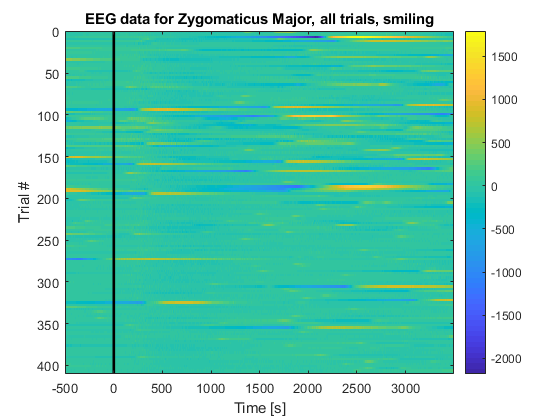

figure(7)
imagesc(times_ms,(1:num_trials),data_ch1(labels == "S pressed",:)); %Image the data from Zygomaticus Major.
colorbar;
xlabel('Time [s]') %Label the x-axis.
ylabel('Trial #') %Label the y-axis.
title("EEG data for Zygomaticus Major, all trials, smiling")
hold on %Indicate time of stimulus onset.
plot([0.25, 0.25], [0 1000], 'k', 'LineWidth', 2)
hold off

%warm colors = high voltages/ cool colors = lower voltages

# EEG data for Ch1, all trials, frowning

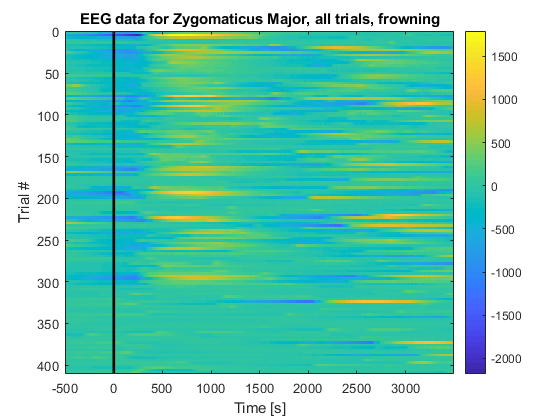

figure(8)
imagesc(times_ms,(1:num_trials),data_ch1(labels == "F pressed",:)); %Image the data from Zygomaticus Major.
colorbar;
xlabel('Time [s]') %Label the x-axis.
ylabel('Trial #') %Label the y-axis.
title("EEG data for Zygomaticus Major, all trials, frowning")
hold on %Indicate time of stimulus onset.
plot([0.25, 0.25], [0 1000], 'k', 'LineWidth', 2)
hold off

%warm colors = high voltages/ cool colors = lower voltages

# Confidence Interval Plot of Ch1 (CLT)

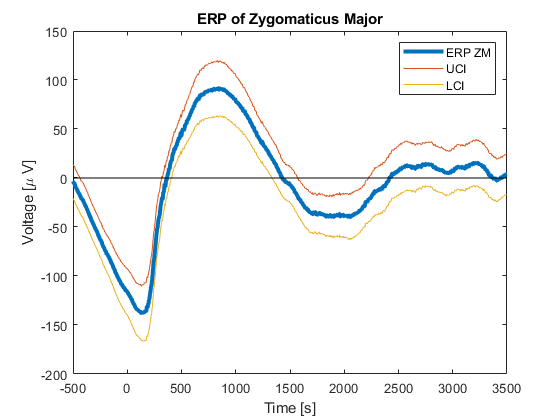

mn1 = mean(data_ch1,1); %Compute mean across trials (the ERP).
sd1 = std(data_ch1,1); %Compute std across trials.
sdmn1=sd1/sqrt(num_trials); %Compute the std of the mean.

figure(9)
plot(times_ms, mn1, 'LineWidth', 3) %Plot the ERP of zygomaticus major.
hold on
plot(times_ms, mn1+2*sdmn1); %... and include the upper Confidence Interval.
plot(times_ms, mn1-2*sdmn1); %... and the lower Confidence Interval.
plot(times_ms, zeros(size(mn1)), 'k') %... add horizontal line at 0.
hold off 

legend("ERP ZM", "UCI", "LCI")
xlabel('Time [s]') %Label the x-axis as time.
ylabel('Voltage [\mu V]') %Label the y-axis as voltage.
title('ERP of Zygomaticus Major') %Provide a useful title.

# Confidence Interval Plot of Ch2 (CLT)

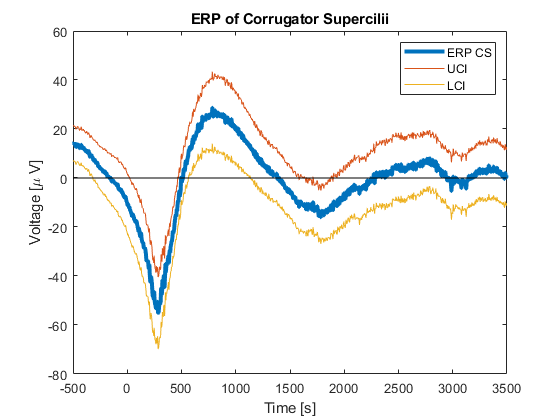

mn2 = mean(data_ch2,1); %Compute mean across trials (the ERP).
sd2 = std(data_ch2,1); %Compute std across trials.
sdmn2=sd2/sqrt(num_trials); %Compute the std of the mean.

figure(10)
plot(times_ms, mn2, 'LineWidth', 3) %Plot the ERP of corrugator supercilii.
hold on
plot(times_ms, mn2+2*sdmn2); %... and include the upper Confidence Interval.
plot(times_ms, mn2-2*sdmn2); %... and the lower Confidence Interval.
plot(times_ms, zeros(size(mn2)), 'k') %... add horizontal line at 0.
hold off 

legend("ERP CS", "UCI", "LCI")
xlabel('Time [s]') %Label the x-axis as time.
ylabel('Voltage [\mu V]') %Label the y-axis as voltage.
title('ERP of Corrugator Supercilii') %Provide a useful title.

# Difference in CI of Ch1 and Ch2 (CLT)

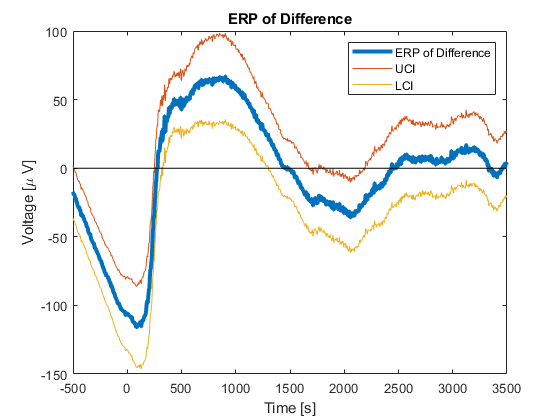

mnD=mn1-mn2; %The differenced ERP,
sdmnD=sqrt(sdmn1.^2 + sdmn2.^2);%...and its standard dev.

figure(11)
plot(times_ms, mnD, 'LineWidth', 3) %Plot the ERP of corrugator supercilii.
hold on
plot(times_ms, mnD+2*sdmnD); %... and include the upper Confidence Interval.
plot(times_ms, mnD-2*sdmnD); %... and the lower Confidence Interval.
plot(times_ms, zeros(size(mnD)), 'k') %... add horizontal line at 0.
hold off 

legend("ERP of Difference", "UCI", "LCI")
xlabel('Time [s]') %Label the x-axis as time.
ylabel('Voltage [\mu V]') %Label the y-axis as voltage.
title('ERP of Difference') %Provide a useful title.

# Confidence Interval Plot of Ch1 (Bootstrapping)

"The advantage of the bootstrapping procedure over other approaches is that this procedure requires few assumptions about the distribution of the statistic of interest, and that we use the observed data to probe the distribution of the statistic."

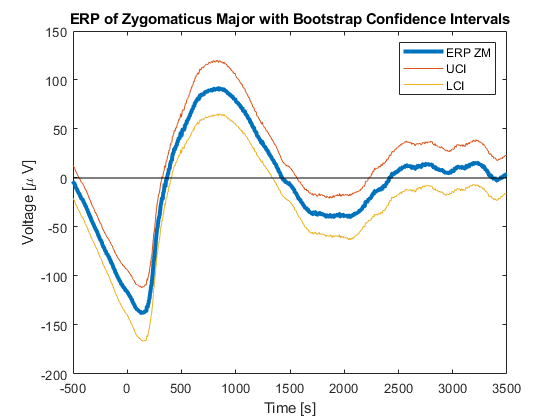

resampled_ERP = zeros(3000,size(data_ch1,2)); %Create empty ERP variable.
for k=1:3000 %For each resampling,
i=randsample(num_trials,num_trials,1); %Draw 1000 integers with replacement from (1,1000);
resampled_data= data_ch1(i,:); %Create the resampled EEG.
resampled_ERP(k,:) = mean(resampled_data,1); %Create the resampled ERP.
end

s_resampled_ERP=sort(resampled_ERP); %Sort each column of resampled ERP.
ciL =s_resampled_ERP(0.025*size(resampled_ERP,1),:); %Determine lower CI.
ciU =s_resampled_ERP(0.975*size(resampled_ERP,1),:); %Determine upper CI.

figure(12)
plot(times_ms, mn1, 'LineWidth', 3) %... plot ERG of zygomaticus major data.
hold on 
plot(times_ms,ciU) %... and upper CI.
plot(times_ms,ciL) %... and plot lower CI,
plot(times_ms, zeros(size(mn1)), 'k') %... add horizontal line at 0.
hold off 

legend("ERP ZM", "UCI", "LCI")
ylabel('Voltage [\mu V]') %Label the y-axis as voltage.
xlabel('Time [s]') %Label the x-axis as time.
title('ERP of Zygomaticus Major with Bootstrap Confidence Intervals')